# 02 Hands On: Continuous Problems - Part 2

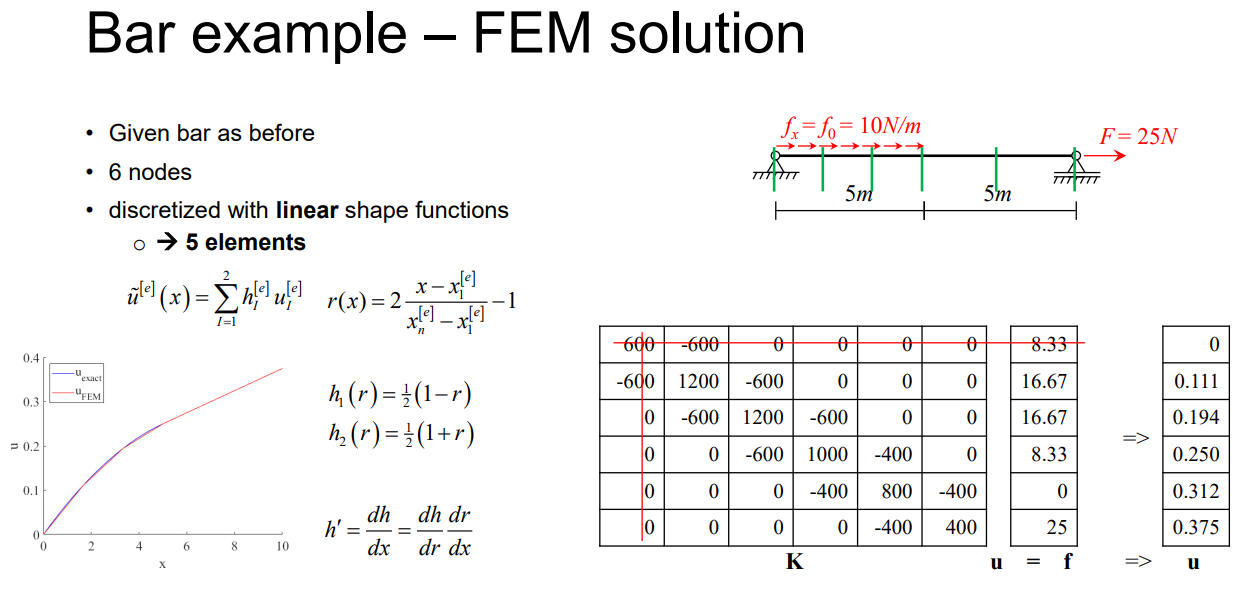

clc; clear all; close all;

EA = 1000;
f0 = 10;
F = 25;
L = 10;

## Analytic solution

### Deformation plot

u1 = @(x) (- (f0 / 2) * x .^ 2 + (F + (f0 * (L / 2))) * x) / EA ;
u2 = @(x) (F * x + (f0 / 2) * (L^2 / 4)) / EA;

f1 = figure; hold on;
fplot(u1, [0, L/2], color = 'b');
fplot(u2, [L/2 L], color = 'b');

### Normal force plot

n1 = @(x) (-f0 * x + F + f0 * (L/2));
n2 = F;

f2 = figure; hold on
fplot(n1, [0, L/2], color = 'b');
fplot(n2, [L/2, L], color = 'b');

## FEM - linear

#### Set up nodes and elements

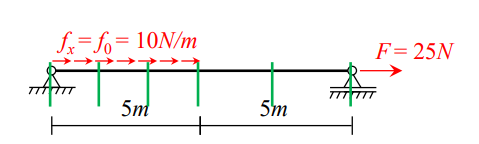

nodes = [0 L/6 L/3 L/2 3/4*L L]';
nNodes = numel(nodes);
nElements = nNodes - 1;

lengths = zeros(nElements, 1);

% get length of every element
for nodeIndex = 2 : nNodes
    lengths(nodeIndex - 1) = nodes(nodeIndex) - nodes(nodeIndex - 1);
end

% line-load
f0FEMlin = [f0, f0, f0, 0, 0];

#### Initialize global system

`K*u=f  ->  u=K\f`

K = zeros(nNodes);
u = zeros(nNodes, 1);
f = zeros(nNodes, 1);
f(end) = F;

#### Assemble stiffness matrix and load vector

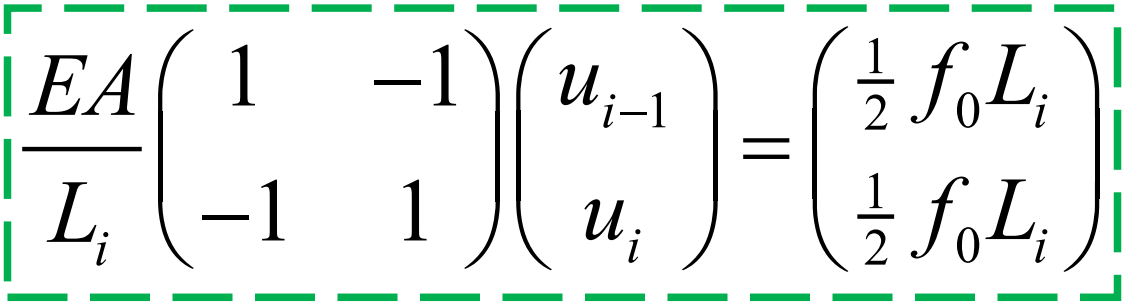

KE = [ 1 -1;
      -1  1];

% add stiffness & force for every element
for e = 1 : nElements
    % stiffness
    K([e, e + 1], [e, e + 1]) = K([e, e + 1], [e, e + 1]) ...   % old part
                                + EA / lengths(e) * KE;         % new part
    % force
    f([e, e + 1]) = f([e, e + 1]) ...
                    + 1/2 * f0FEMlin(e) * lengths(e);
end

u(2:end) = K(2:end, 2:end) \ f(2:end);

### Deformation plot

figure(f1)
plot(nodes, u, color = 'r');
legend({'u_{exact}', '', 'u_{FEM,1}'})

### Normal force plot

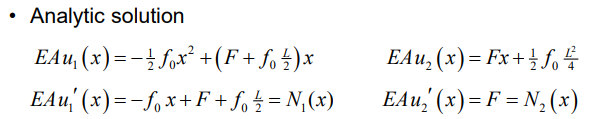

`u = (x_i - x)/(L_i) *`` u(i-1)`` + (x - x_{i-1})/(L_i) * ``u(i)`

`N = EA *u'`

`    --> N = EA * -1/L_i *`` u(i-1) ``+ 1/L_i * ``u(i)`

figure(f2)
for e = 1 : nElements
    Ni = -1 / lengths(e) * u(e) + 1 / lengths(e) * u(e + 1);
    plot([nodes(e), nodes(e + 1)], EA * [Ni, Ni], color = "r");
end
legend({'N_{exact}', '', 'N_{FEM,1}'})

## Generalize approach for linear elements

Set up elements

elements = [1, 2; 
            2, 3; 
            3, 4; 
            4, 5; 
            5, 6];
nodesPerElement = 2;
dofPerElement = nodesPerElement;
degree = 1;

% Initialize global system fo generalized approach
Kg = zeros(nNodes);
ug = zeros(nNodes, 1);
fg = zeros(nNodes, 1);
fg(end) = F;

% Assemble stiffness matrix and load vector
ke = EA;

% consider every element
for e = 1 : nElements
    
    % prepare stiffness matrix and load vector for THIS element
    KE = zeros(dofPerElement);
    fE = zeros(dofPerElement, 1);

    firstNode = nodes(elements(e, 1));
    lastNode = nodes(elements(e, end));

    % get stiffness matrix for THIS element
    for j = 1 : dofPerElement
        for i = j : dofPerElement

            % Stiffness: integral from first node to last node: (k * h_i' * h_j') dx
            intK = @(x) ke * shapeFunctions(x, firstNode, lastNode, i, 1, degree) .* ...
                             shapeFunctions(x, firstNode, lastNode, j, 1, degree);
            
            KE(i, j) = integral(intK, firstNode, lastNode);
            KE(j, i) = KE(i, j);

        end

        % Load: integral from first node to last node: (f h_j) dx
        intF = @(x) f0FEMlin(e) * shapeFunctions(x, firstNode, lastNode, j, 0, degree);
        % get load vector for THIS element
        fE(j) = integral(intF, firstNode, lastNode);

    end

    % Assemble THIS element stiffness matrix and load into global system
    indices = elements(e, :);
    Kg(indices, indices) = Kg(indices, indices) + KE;
    fg(indices) = fg(indices) + fE;
end 

ug(2:end) = K(2:end, 2:end) \ f(2:end)

## FEM - quadratic

Set up nodes

nNodes = 5;
nodes = linspace(0, L, nNodes);

% Set up Elements
nElements = 2;
elements = [1, 2, 3;
            3, 4, 5];
nodesPerElement = 3;
dofPerElement = nodesPerElement;
degree = 2;

% Line load per element
f0FEMquad = [f0; 0];

% Initialize global system
Kq = zeros(nNodes);
uq = zeros(nNodes, 1);
fq = zeros(nNodes, 1);
fq(end) = F;

% Assemble stiffness matrix and load vector
ke = EA;
for e = 1 : nElements
    KE = zeros(3);
    fE = zeros(3, 1);

    firstNode = nodes(elements(e, 1));
    lastNode = nodes(elements(e, end));

    for j = 1 : dofPerElement
        for i = j : dofPerElement
            
            intK = @(x) ke * shapeFunctions(x, firstNode, lastNode, i, 1, degree) .* ...
                             shapeFunctions(x, firstNode, lastNode, j, 1, degree);

            KE(i, j) = integral(intK, firstNode, lastNode);
            KE(j, i) = KE(i, j);
        end
        intF = @(x) f0FEMquad(e) * shapeFunctions(x, firstNode, lastNode, j, 0, degree);
        fE(j) = integral(intF, firstNode, lastNode);
    end
    indices = elements(e, :);
    Kq(indices, indices)    = Kq(indices, indices)  + KE;
    fq(indices)             = fq(indices)           + fE;
end
uq(2 : end) = Kq(2:end, 2:end) \ fq(2:end)

### Deformation plot

% Plot by looping over elements and plotting u^[e](x) = sum (h_i * u^[e]_i) for all nodes i in element
figure(1)
for e = 1 : nElements
    indices = elements(e, :);
    ue = uq(indices);

    firstNode = nodes(elements(e, 1));
    lastNode = nodes(elements(e, end));

    xPlot = firstNode : 0.01 : lastNode;
    uPlot = shapeFunctions(xPlot, firstNode, lastNode, [1, 2, 3], 0, 2)' * ue;
    
    plot(xPlot, uPlot, color = 'g');
    legend({'u_{exact}', '', 'u_{FEM}', 'u_{FEM,2}'})
end

## Additional functions

function h = shapeFunctions(x, firstNode, lastNode, index, derivative, degree)
    % Evaluate and return shape function or derivative for 1D element
    % INPUT
    %   x (array)               Positions for evaluation of shape functions inside element
    %   firstNode (scalar)      Coordinate of first node for element
    %   lastNode (scalar)       Coordinate of last node for element
    %   index   (scalar/array)  Index or indices for shape functions to be returned
    %   derivative (bool)       Switch to return derivatives
    %   degree (scalar)         Degree for shape functions (1/2)
    % OUTPUT
    %   h (scalar/array)        Evaluation of shape functions or derivatives for given input x and index
    
    r = 2 * (x - firstNode) / (lastNode - firstNode) - 1;
    drdx = 2 / (lastNode - firstNode);
    switch degree
        case 1
            if derivative
                h = [-1/2 * ones(size(x));
                    1/2 * ones(size(x))] * drdx;
            else
                h = [(1 - r) ./ 2;
                     (1 + r) ./ 2];
            end
        case 2
            if derivative
                h = [- 1 / 2 + r;
                     - 2 * r;
                       1 / 2 + r] .* drdx;
            else
                h = [(1 - r)./2 - (1 - r.^2) ./ 2;
                      1 - r.^2;
                     (1 + r) ./ 2 - (1 - r.^2) ./ 2];
            end
        otherwise
            error('Shape function not implemented')
    end
    h = h(index, :);
end